% Init

bagPath = "E:\ICRA2\radar_high_res\2020-07-13-14-10-09.bag";

nFast = 304;
nRx = 4;
nTx = 2;    
nSlow = 256;
k = 4;

% Load radar data
radarData = extract_data(bagPath, 1, nFast, nRx, nTx, nSlow, k);

Opening bag
Extracting radar messages
building dataCube(s)



% Process radar data 
radarData = rda_proc_001(radarData);

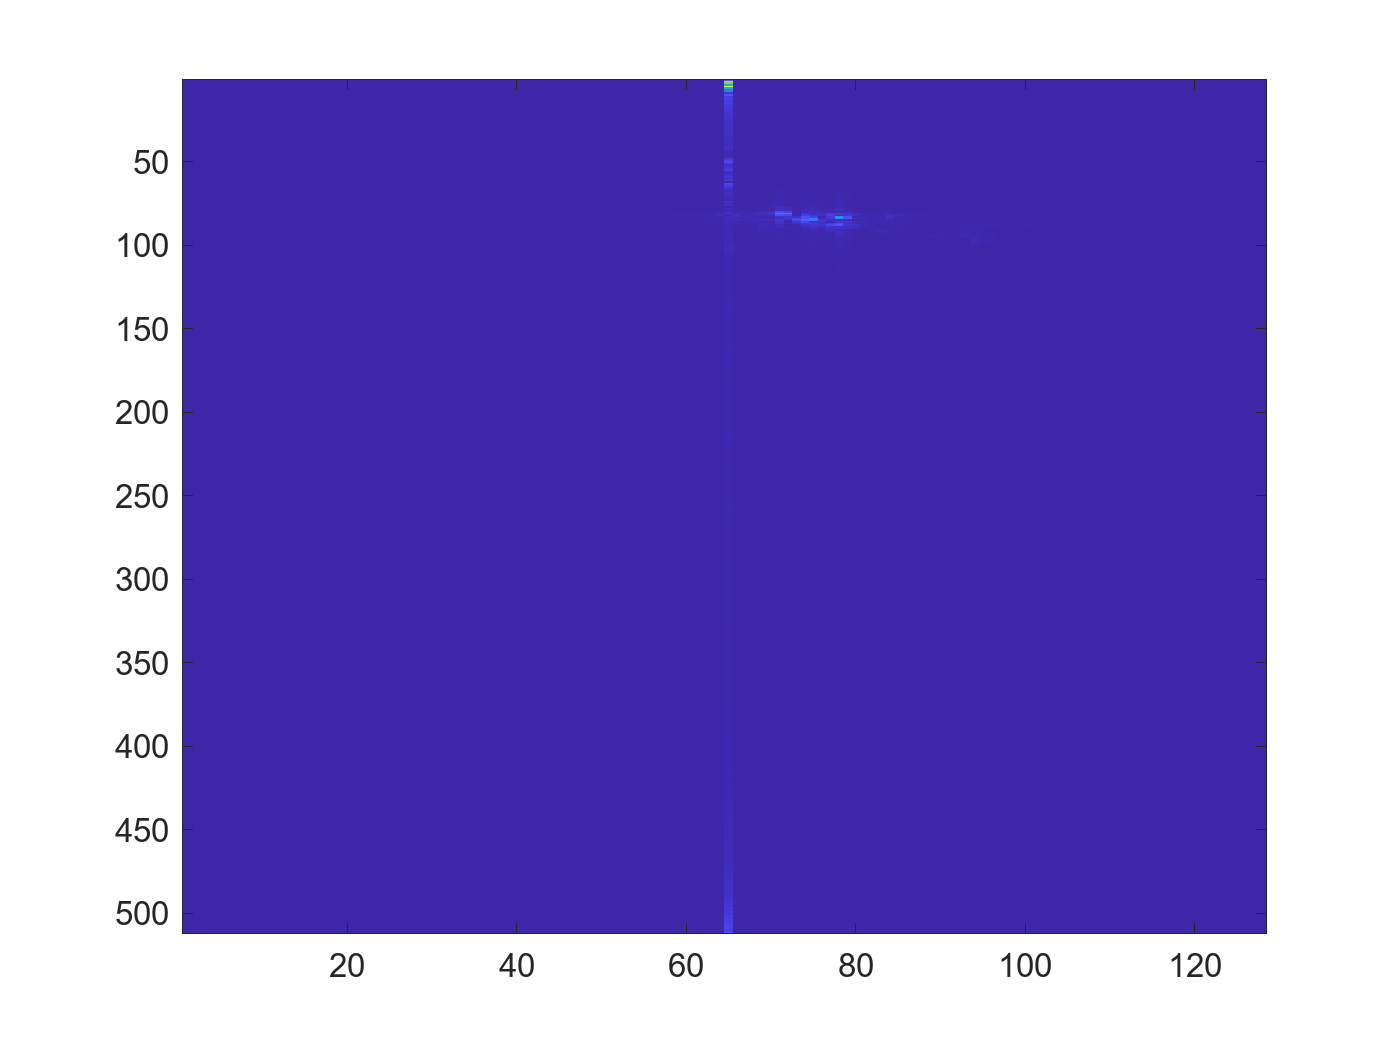

% Visualise radar data 
imagesc((abs(squeeze(radarData{1}.rdProc(:, 1, :)))));

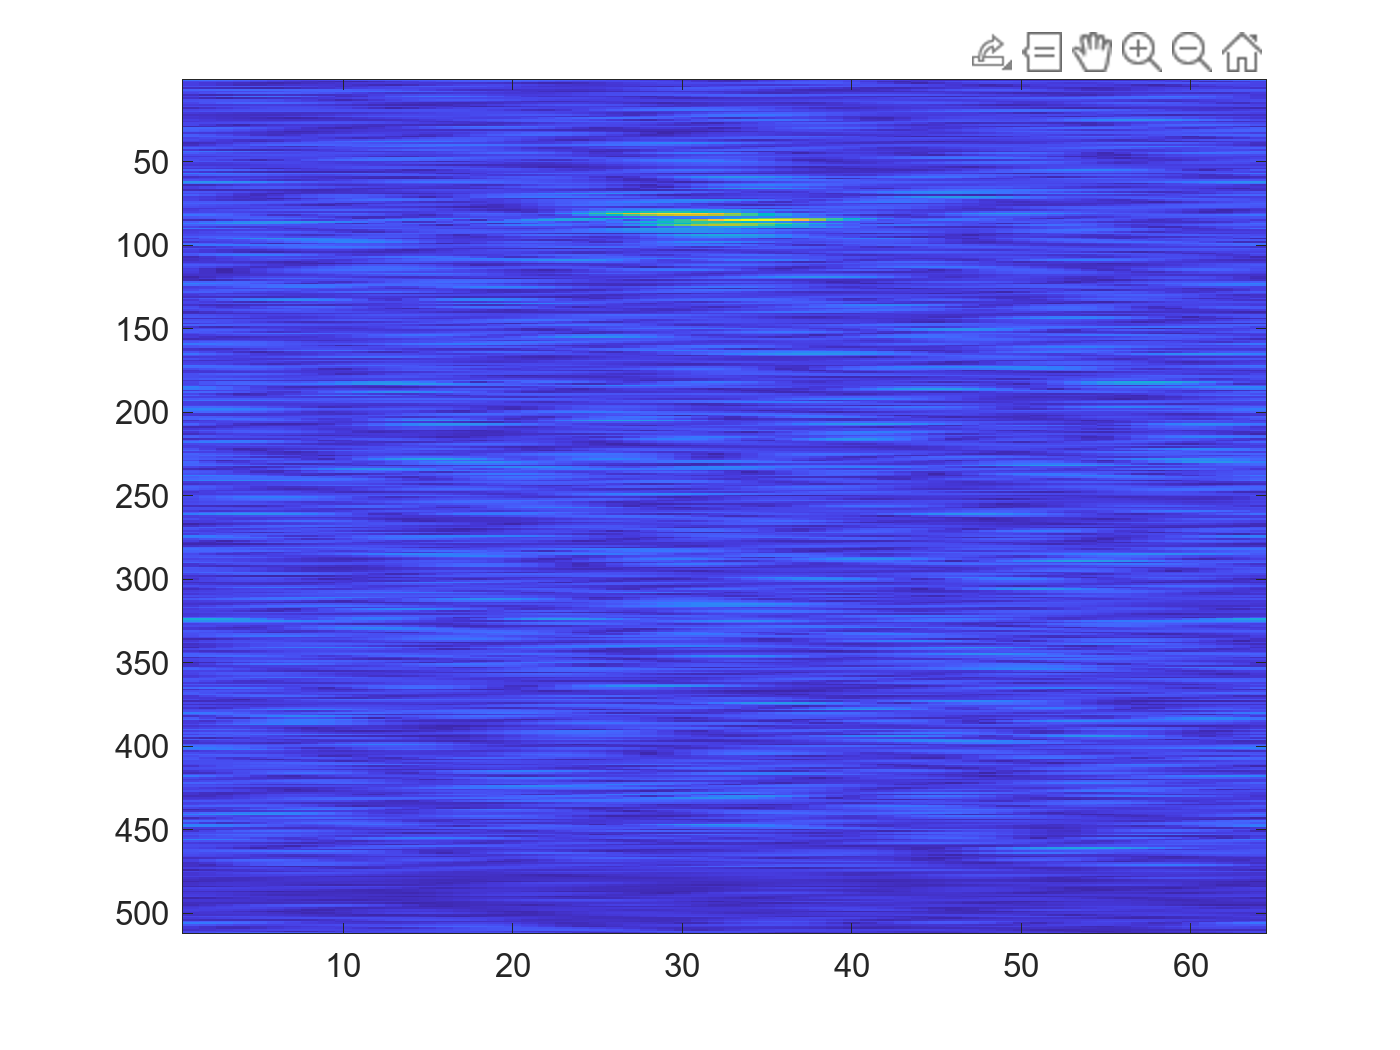


imagesc((abs(squeeze(radarData{1}.raProc(:, :, 1)))));